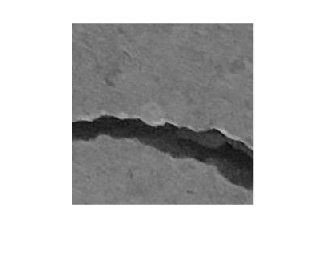

img = im2gray(imread("00187.jpg"));
imshow(img)

Binarizing, it to divide it into B and W

BW = imbinarize(img)

BW = 227×227 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1 

imbinarize work's on Otsu's Method which finds a threshold value based on the distribution of pixel intensities

Using graythresh function to find the threshold value in the above function

graythresh(img)

ans = 0.3255

threshintensity = graythresh(img) * 255

threshintensity = 83

Visualising the segmented Image

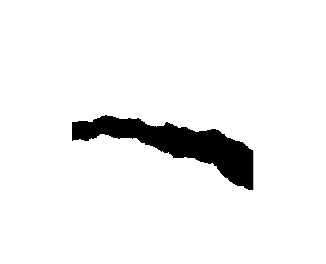

imshow(BW)

Inverting the black and White Image

BW = ~BW

BW = 227×227 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

Comparing the Original with the new image

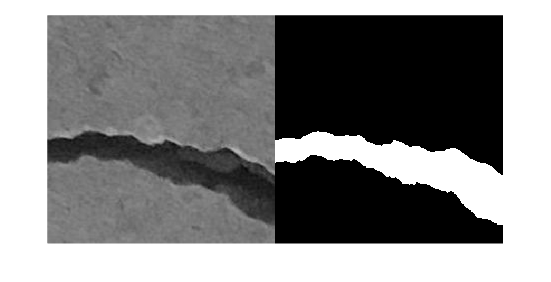

montage({img,BW})

Number of Non Zero Elements Function

nnz(BW)

ans = 7846

Creating a copy of the image variable to put a mask on it

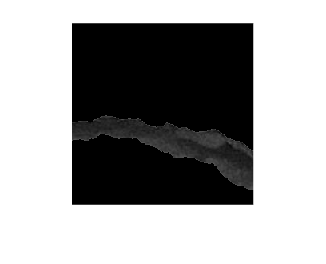

maskedImg = img;
maskedImg(~BW)=0;
imshow(maskedImg);

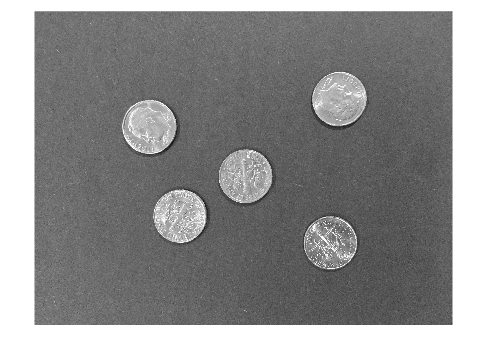

dimes = im2gray(imread("dimes.jpg"));
imshow(dimes)

graythresh(dimes)*255

ans = 0.5608

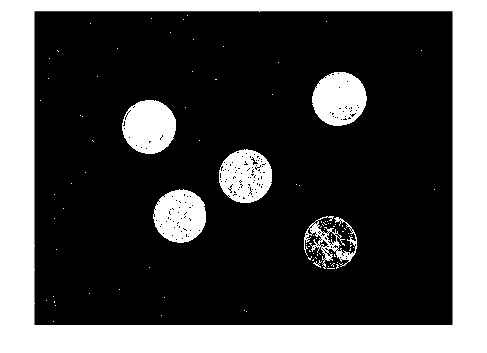

BWdimes = imbinarize(dimes,graythresh(dimes));
imshow(BWdimes)

[T,EM] = graythresh(dimes)

T = 0.5608

EM = 0.6967

nnz(BWdimes)

ans = 594617

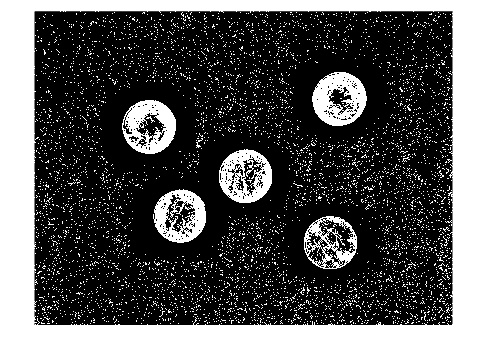

BWdimesAdaptive = imbinarize(dimes,"adaptive");
imshow(BWdimesAdaptive)

Importing a Thin Crack

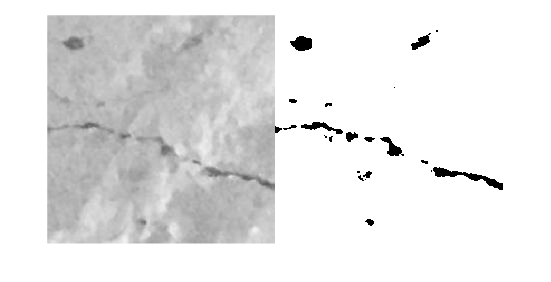

thinCrack = im2gray(imread("00051.jpg"));
BWThinCrack = imbinarize(thinCrack,0.63);
montage({thinCrack,BWThinCrack})

Trying with Rice - Learning Adaptive thresholding

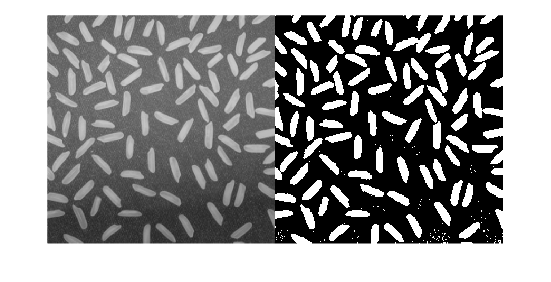

rice = imread("rice.png");
BWrice = imbinarize(rice,"adaptive");
montage({rice,BWrice})

Non-Binary Segmentation : XRAY image of an arm

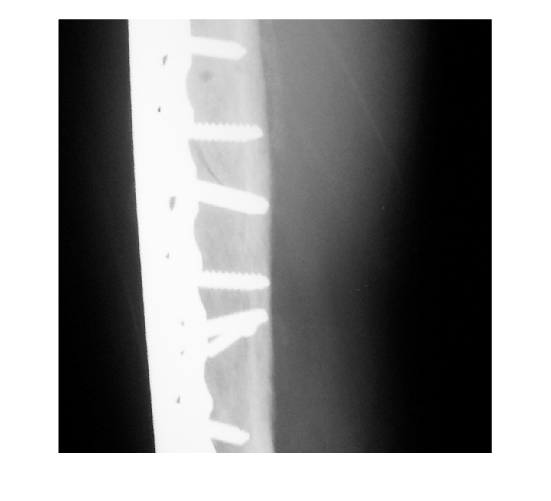

armxrayimage = imread("armxray.png");
imshow(armxrayimage)

threshValues = multithresh(armxrayimage,3)

threshValues = 1×3 uint8 row vector
    54   147   223


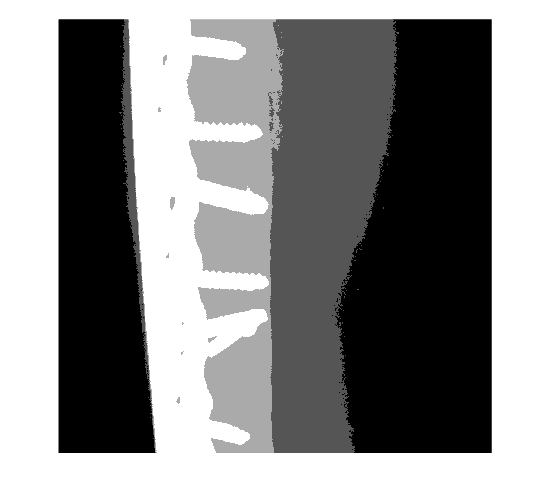

labels= imquantize(armxrayimage,threshValues);
imshow(labels,[])

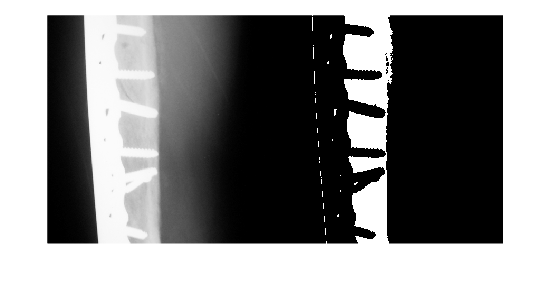

label3 = labels == 3;
montage({armxrayimage,label3})

Trying Binary segmentation upon the arm xray

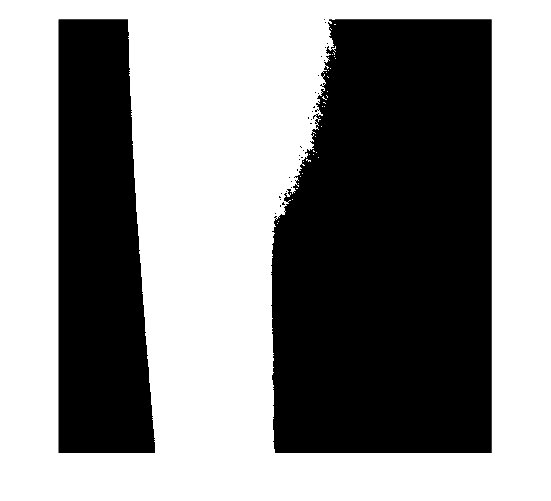

BWarm = imbinarize(armxrayimage);
imshow(BWarm)

BWarm2 = imbinarize(armxrayimage,"adaptive");
imshow(BWarm2)

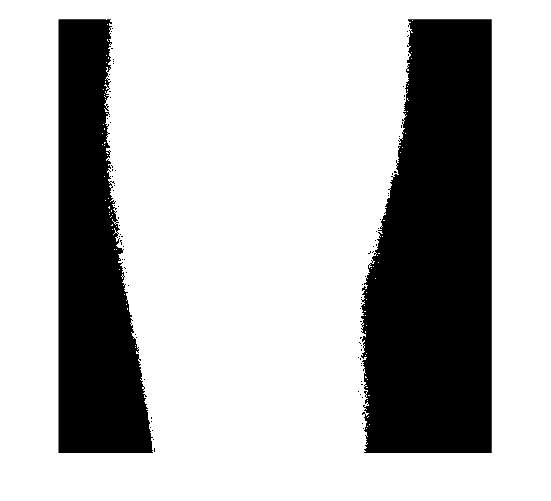

BWarm3 = imbinarize(armxrayimage,0.123);
imshow(BWarm3)